Steps

- Set up simple heat cooling equation

- set up heat dissapation vs time

- Predict last cell ambient air temp and properites

- Find how long to run tests for

- Make equations to estimate how much that cell should dissapate

- justify cell temperature 

To learn

- Repeated non fully developed flow

Tasks

Draft Setup plan

Create list of what equipment is needed

Make machining drawings

To make this script work and be able to predict stuff

- The nusselt number has to be found. This can be found with the below equation. 

I belive that this equation belives that that the Hydralic Diameter D is constant, of which in enepaq modules it is not. Also, the heat transfer coeff H is dependant on many other factors. 

I suppose that If you were able to find a heat transfer coefficent for a one test setup at one speed and were able to find out the reynolds number you could

- Assume the prandl number is roughly constant

- Find C

The enepaq module is a weird shape, so I'm not too sure if they reynolds number could be found. I would also want to pay attention to 

- Entrance/Exit effects

- If the the changes in fluid temperature are significant enough

If I can think of a plan for approximating this in order of effort

- Run tests at differing fan rates, accurately measure intake/exit speed/pressure. If extrapolation is needed use the general trends of increased mass flow vs heat disspation. The mock segment will be reasonable similar, and the properties of aluminum are reasonable close to cells. This value will likely be quite good. 

- Look more into the 7.52 question pasted above. Put a 3d printer heater and temperature sensor in a mock cell. Supply an exact amount of current to the heater cartridge in the cell. Place this cell at the end of the pack and figure out what the effective hydralic diameter is. This represents q in the equation 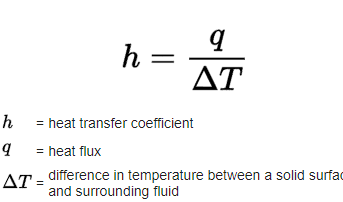 DeltaT is known from the measured cell temp(from a thermocouple). This means we know h(avg) once we note how much area m^2 is exposed to airflow. After this I assume that the reynolds number is averaged through the module(it might not be??). This should allow me to find C. Once I have C I can increase flow, increase the reynolds number and see if it correlates to the experimental results. This could also be done with very finely measuring the temperature of the cell and finding how much heat is dissapated off it. The heater catridge would just allow for steady state. 

DiameterCells = 18.3/1000;%diameter in m
r = DiameterCells/2;
HeightCell = 65/1000;
VolumeCell = HeightCell*r^2*pi;

ThermalConductivityAlum =	167;% W/m-K
DensityAlum =	2.7*1000;% g/L
SpecificHeatCapacityAlum =	0.896*1000; %J/kg-°C
heatCapCell = DensityAlum * VolumeCell * SpecificHeatCapacityAlum;

heatCapCell = 41.3597